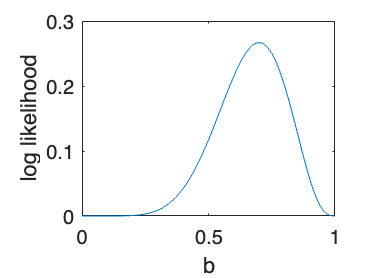

% 最尤推定
% 直感的にもわかるシンプルな確率について一般に求める

% 試行においてと, n 回中 x 回表が出るとき
n=10;
x=7;

b=0:0.01:1;

% L(b;x) = nCx * b^x (1-b)^(n-x)
logL=nchoosek(n,x)*b.^x.*(1-b).^(n-x);
plot(b, logL);
xlabel('b');
ylabel('log likelihood')


% 最大値を求める
[M, I] = max(logL);

% 最大となる x の値
argM = b(I)

argM = 0.7000

% 最尤推定
% 正規分布

% x_1, ... , x_n として, 平均 0, 分散 1 の正規分布に従う
N=100;
x=randn(1, N);

sigma2=0.5:0.01:3;

% 対数をとることにより, 総積 -> 総和にする
logL = -N/2*log(2*pi)-N/2*log(sigma2)-sum(x.^2)./(2*sigma2)

logL =  -132.8158 -132.3239 -131.8699 -131.4511 -131.0653 -130.7104 -130.3844 -130.0855 -129.8120 -129.5624 -129.3353 -129.1293 -128.9431 -128.7756 -128.6258 -128.4926 -128.3751 -128.2724 -128.1837 -128.1083 -128.0453 -127.9942 -127.9542 -127.9249 -127.9057 -127.8959 -127.8952 -127.9031 -127.9190 -127.9427 -127.9737 -128.0117 -128.0562 -128.1071 -128.1638 -128.2263 -128.2941 -128.3671 -128.4449 -128.5274 -128.6143 -128.7054 -128.8005 -128.8993 -129.0018 -129.1077 -129.2170 -129.3293 -129.4446 -129.5627


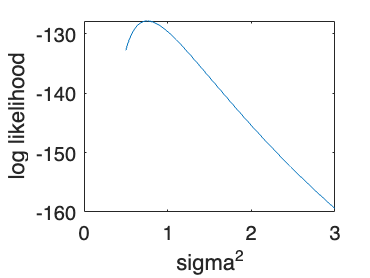


plot(sigma2, logL);

xlabel('sigma^2');
ylabel('log likelihood');

% 過去問

% 正規分布
% x_1, ... , x_n として, 平均 0, 分散 1 の正規分布に従う
N=100;
x=[5,7,1,4,2,-1];

% 分散
sigma2=0.5:0.01:3;

% 対数をとることにより, 総積 -> 総和にする
logL = -N/2*log(2*pi)-N/2*log(sigma2)-sum(x.^2)./(2*sigma2)

logL =  -153.2365 -152.3443 -151.5052 -150.7160 -149.9734 -149.2747 -148.6172 -147.9984 -147.4161 -146.8681 -146.3526 -145.8676 -145.4114 -144.9826 -144.5795 -144.2009 -143.8454 -143.5118 -143.1990 -142.9059 -142.6315 -142.3750 -142.1353 -141.9117 -141.7035 -141.5097 -141.3299 -141.1633 -141.0092 -140.8672 -140.7367 -140.6171 -140.5079 -140.4087 -140.3190 -140.2385 -140.1667 -140.1032 -140.0476 -139.9997 -139.9592 -139.9256 -139.8987 -139.8782 -139.8639 -139.8555 -139.8528 -139.8554 -139.8633 -139.8762


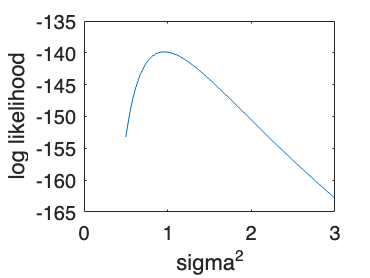


plot(sigma2, logL);

xlabel('sigma^2');
ylabel('log likelihood');


% 最大値を求める
[M, I] = max(logL);

% 最大となる x の値
argM = b(I)

argM = 0.4600